3. Implementati o metoda de cuadratura adaptiva pentru formula repetata a lui Simpson, una pentru metoda trapezelor si una pentru metoda dreptunghiurilor.

f = @(x) 1./(1+exp(-x));
a = -4; b = 4;
tol=1e-4;
adapt_trapezoidal = adaptquad(a, b, f, tol, @trapezoidal)

adapt_trapezoidal = 3.6000

adapt_simpson = adaptquad(a, b, f, tol, @simpson)

adapt_simpson = 3.4666

adapt_rectangular = adaptquad(a, b, f, tol, @rectangular)

adapt_rectangular = 4.0000

real = integral(f, a, b)

real = 4.0000

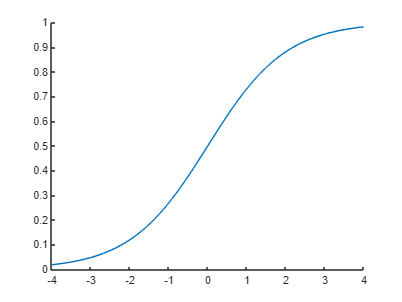


x = linspace(a,b);
clf; hold on;
plot(x, f(x))
hold off;

function A=adaptquad(a,b,f,tol, met)
    m=5;
    if abs(met(a,b,f,m)-met(a,b,f,2*m))<tol
        A = met(a,b,f,2*m);
    else
        A = adaptquad(a,(a+b)/2,f,tol,met)+adaptquad((a+b)/2,b,f,tol,met);
    end
end

function A = trapezoidal(a, b, f, n)        
    y = f(linspace(a,b,n));
    A = ((b-a)/(2*n))*(y(1)+y(n)+2*sum(y(2:n-1)));
end

function A = simpson(a, b, f, n)
    y = f(linspace(a,b,n));    
    m = floor(n/2);
    A = ((b-a)/(6*m))*(y(1)+y(2*m) + 2*sum(y(3:2:(2*m-1))) + 4*sum(y(2:2:(2*m-2))));
end

function A = rectangular(a, b, f, n)
    y = f(linspace(a,b,n));    
    A = (b-a)/n*sum(y);
end
